clear;

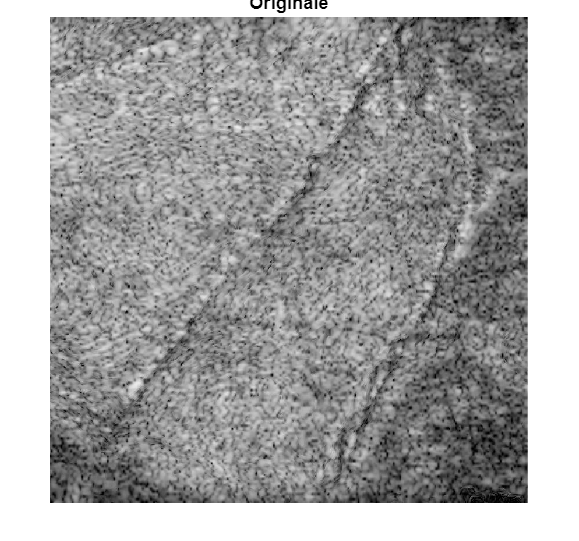

%APPLICAZIONE FILTRO WAVELET
inputImage = imread("imageGeneratedFrom3D\04-09-2023_Scavone_000\immagine_5_0.2772.jpg");
figure;imshow(inputImage); title("Originale")

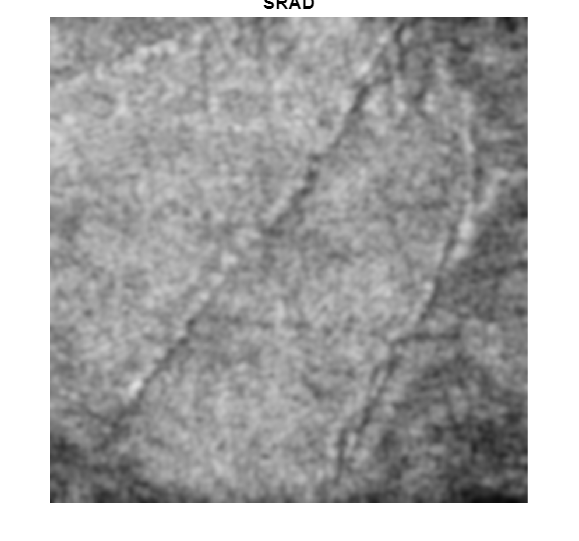

rect = [10 15 40 40]; 
[filteredImage] = SRAD(inputImage,40,0.9,rect);
figure;imshow(filteredImage); title("SRAD")

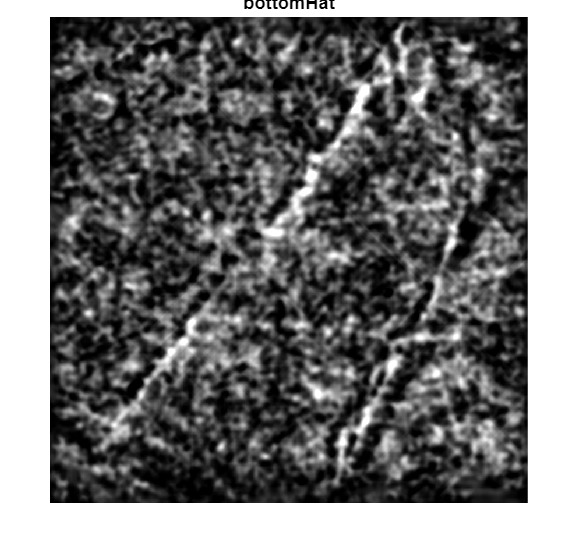


%BOTTOM HAT FILTER 4 DIREZIONI
bottomHatFiltered = bottomhat4way(filteredImage);
imshow(bottomHatFiltered); title('bottomHat'); figure;

%imwrite(bottomHatFiltered, strcat(filename,'_BotHat.jpg'));
 

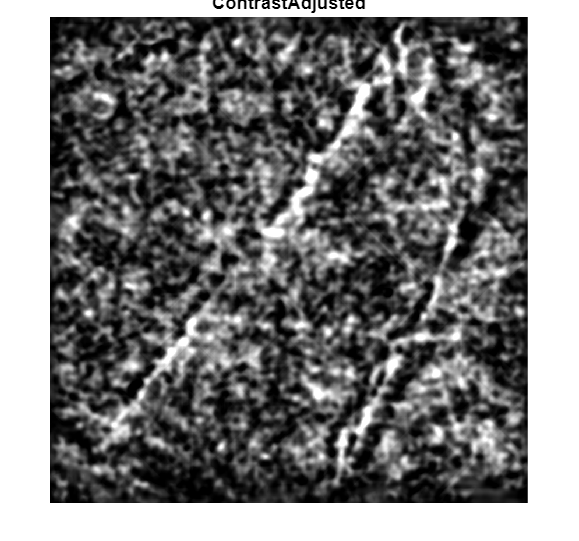

%AUMENTO CONTRASTO
contrastAdjusted = imadjust(bottomHatFiltered,stretchlim(bottomHatFiltered),[]);
imshow(contrastAdjusted); title('ContrastAdjusted'); figure;

%imwrite(contrastAdjusted,strcat(filename,'_contrastAdj.jpg'));


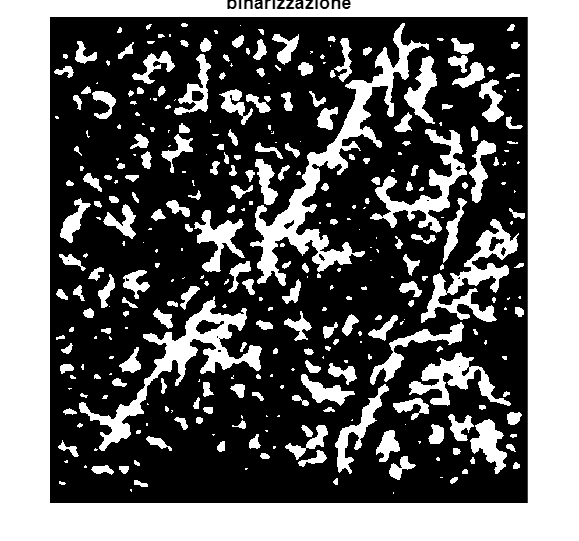



%BINARIZZAZIONE
A = contrastAdjusted;
meanValue=mean2(A);
threshold = meanValue*1.6;   % più è alto il fattore di scala meno dettagli saranno presenti
A_bw = A > threshold;
imshow(A_bw); title('binarizzazione'); figure;

%imwrite(A_bw, strcat(filename,'_Bin.jpg'));


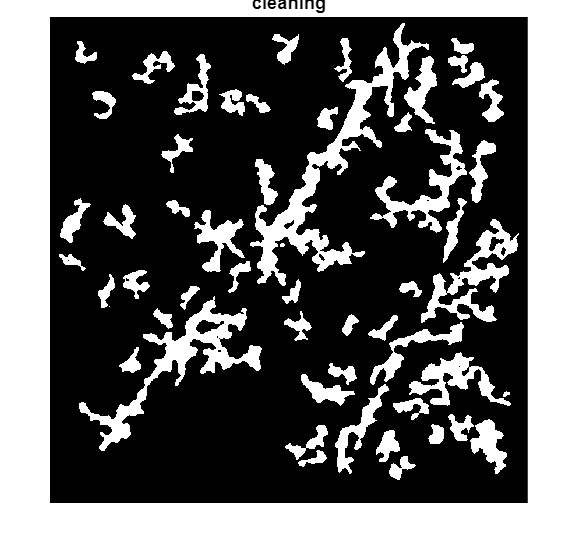


%CLEANING
CC= bwconncomp(A_bw);
S = regionprops(CC, 'Area');
L = labelmatrix(CC);  
BW2 = ismember(L, find([S.Area] >= 500));
imshow(BW2); title('cleaning'); figure;

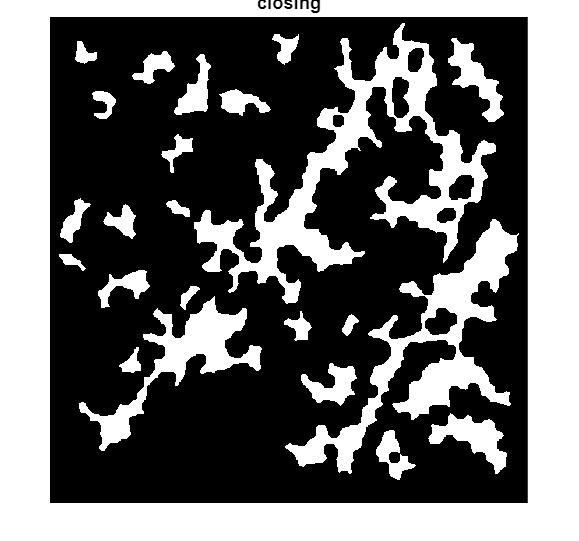


%imwrite(BW2, strcat(filename,'_cleaning.jpg'));

%CLOSING
se=strel('disk', 10);
closing=imclose(BW2, se);
imshow(closing); title('closing'); figure;

%imwrite(closing, strcat(filename,'_closing.jpg'));

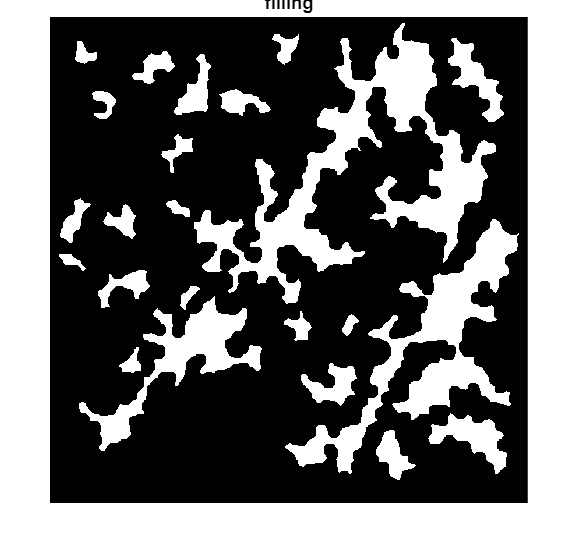



%imwrite(filling, strcat(filename,'_filling.jpg'));
filling= imfill(closing,'holes');
imshow(filling); title('filling'); figure;

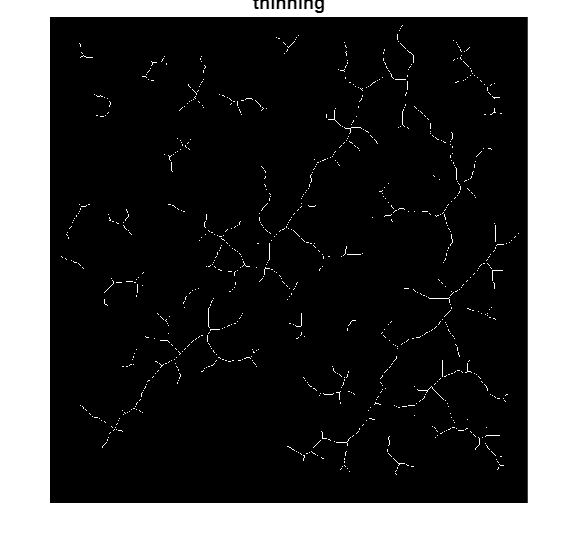


%THINNING
thinning= bwmorph(filling, 'thin', inf);
imshow(thinning);title('thinning');figure;

%imwrite(thinning, strcat(filename,'thinning.jpg'));

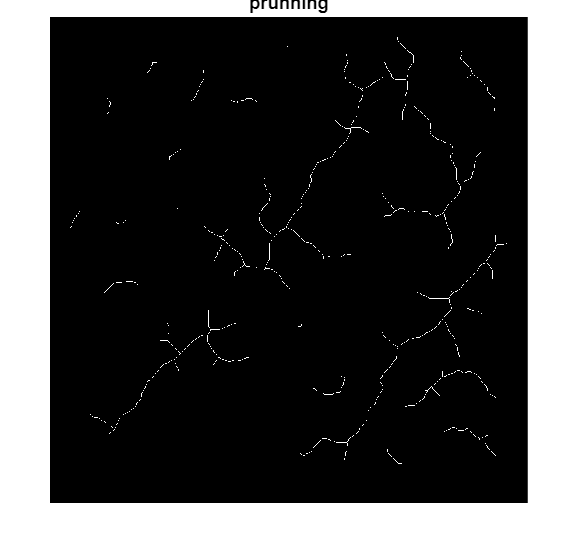


%PRUNNING
prun= bwmorph( thinning, 'spur', 21);
imshow(prun);title('prunning');figure;

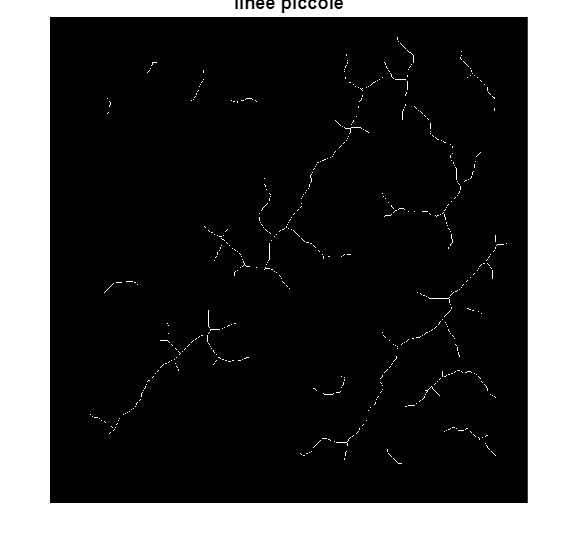

%imwrite(prun, strcat(filename,'_prunning.jpg'));

%CLEANING LINEE PICCOLE
BWz = bwareaopen(prun, 30);
imshow(BWz);title('linee piccole');figure;

%imwrite(BWz, strcat(filename,'_lineePicc.jpg'));

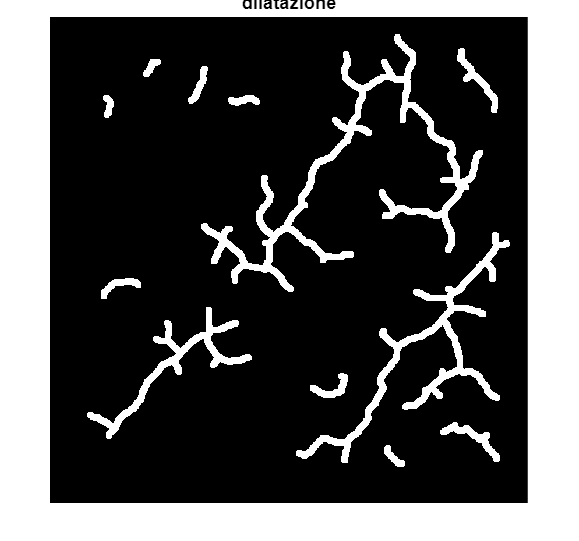


%DILATAZIONE WARING RIMETTERE COME PRIMA DISK 6
dilatation_mask= strel('disk', 6);
dilatedImageDat= imdilate(BWz, dilatation_mask);
imshow(dilatedImageDat); title('dilatazione'); figure;

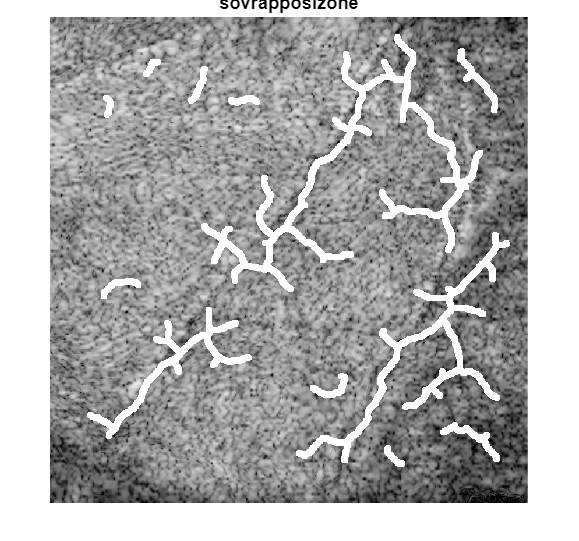


%dlmwrite(strcat(filename,'.dat'),dilatedImageDat);
%imwrite(dilatedImageDat,strcat(fullpathName,'_dilatazione.jpg'))

rgbImage = cat(3, inputImage, inputImage, inputImage);
%SOVRAPPOSIZIONE %%WARNING:RIMETTERE COME PRIMA
[m n1]= size(A);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImageDat(i,j)==1
        %inputImage(i,j)=255;
        rgbImage(i,j,1)=255;
        rgbImage(i,j,2)=255;
        rgbImage(i,j,3)=255;
        end 
    end 
 end	 

imshow(rgbImage);title('sovrapposizone'); figure;